# Linearized Kalman Filter Tuning

This does monte carlo simulations to tune the LKF. 

% bringing in simulation data and provided data
load sim_setup.mat
load orbitdetermination-finalproj_data_2023_11_14.mat

% Bringing in required functions and variables
addpath('./functions/')

## Simulation Settings and Useful Constants

m = length(a_SRP);                      % number of inputs equals the length of this vector
p = 2;                                  % number of measurement variables per landmark
x_0 = [r_nom; dr_nom];                  % initial state
n = length(x_0);                        % number of state variables
dt = dt_int;                            % chosen step size
t_obs = unique(y_table(:, 1));          % times of observations [s]
t = 0:dt:t_f;                           % time vector for LKF
steps = length(t);                      % number of time steps in used in LKF
steps_obs = length(t_obs);              % number of observations

% --- number of landmarks to use --- %
num_marks = length(pos_lmks_A);
% num_marks = 5;
lps = pos_lmks_A(:,1:num_marks);

## ODE Solution with No Noise

This will serve as the nominal states, in which noise gets added to it to create the truth states.

% pure ODE solution with no noise
options = odeset('RelTol',1e-12);               % ODE45 options
[~,x_nom] = ode45(@(t_in,x_in) orbit(t_in,x_in,a_SRP,mu_A), t, x_0', options); 

## System Matrices and Noise

These are static.

% --- Static system matrices ---
% CT B matrix
B = zeros(n,m);
B(4:end,:) = eye(3);

% CT Gamma matrix
Gamma = zeros(n,m);
Gamma(4:end,:) = eye(3);

% CT Noise matrices
W = eye(m)*sig_w^2;             % CT process noise matrix
V = diag([sig_u^2,sig_v^2]);    % CT instrument noise matrix
R = V;                          % measurement noise is already discretized, and should not be divided by the timestep.

% Fixed LKF process noise matrix
Omega = Gamma * dt;             % Approximation from lecture 24, slide 14
Q_kf_start = sig_w^2 *  [eye(m)/3*(dt^3),eye(m)/2*(dt^2);
                        eye(m)/2*(dt^2),eye(m)*(dt)];

## Monte Carlo Simulation

Varying the pertibations that cause noise to be added to the truth state. 

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%% --- Global Monte Carlo Settings -- %%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
num_sims = 25;                                  % number of simulations to do
use_process_noise = true;
use_meas_noise = true;                          % Set true to include measurement noise in truth measurements
use_vanLoans_Q = false;                         % Set true to use the Q noise matrix calculated by Van Loan's method. 
                                                % Set false to use the static Q_kf matrix defined above.
rand_truth_pert = false;                         % set true to use a different LKF initial pertibation for each simulation.                     
trust_scale = 1e0;                              % LKF initial uncertainty scaling factor (Adjusting P_0 for the filter)
process_noise_scale = 1e12;                      % LKF process noise matrix scaling factor (Adjusting Q for the filter)
meas_noise_scale = 1e0;                         % LKF measurement matrix scaling factor (Adjusting R for the filter)

% --- Applying noise scaling factors --- %
Q_kf = Q_kf_start*process_noise_scale;

% --- Defining the uncertainty/pertibations --- % 
pos_uncert = ones(1,3)*1e-3;                    % position 2-sigma uncertainty on order of 5 meters
vel_uncert = ones(1,3)*1e-9;                    % velocity '                           ' of 0.5mm/s
x_pert = [ones(3,1)*2e-3; ones(3,1)*2e-6];               % Random initial uncertainty gerated from uncertainty matrix
P_0 = diag((x_pert./3).^2);  % Initial uncertainty matrix


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%% --- Monte Carlo Loop -- %%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Important things to save each for loop
e_X_all = zeros(n,steps,num_sims);
e_y_all = zeros(p*num_marks,steps_obs,num_sims);
eps_X_all = zeros(steps,num_sims);
eps_y_all = zeros(steps_obs,num_sims);
P_plus_all = ones(n,n,steps,num_sims)*NaN;

% running each simulation
for sim = 1:num_sims
    % % -- initial uncertainty and pertibations --- %
    % x_pert = zeros(n,1);                            % Trying with the nominal case
    % if rand_truth_pert
    %     x_pert = mvnrnd(zeros(n,1),P_0)';             % Random initial uncertainty gerated from uncertainty matrix
    % end
                
    %%%%%%%%%%%%%%%%%%%%%%%%%%%
    %%% --- Truth Model --- %%%
    %%%%%%%%%%%%%%%%%%%%%%%%%%%
    % -- State Truth Model --- %
    % This is a perfect ODE solution from a slightly different starting point each time. 
    if use_process_noise
        % Performing non-linear simulation with added noise
        x_truth = zeros(steps,n);                       % initializing state vector
        x_truth(1,:) = x_0' + x_pert';
        for k = 2:steps
            % Calculating true state with noise, based on non-linear ODE solver 
            % Solving the ODE over this time step
            [t_ode,x_ode45] = ode45(@(t_in,x_in) orbit_noise(t_in,x_in,a_SRP,mu_A,W), [t(k-1), t(k)], x_truth(k-1,:), options);
            [~,k_idx] = min(abs(t_ode-t(k)));
            x_truth(k,:) = x_ode45(k_idx,:);
        end
    else 
        [~,x_truth] = ode45(@(t_in,x_in) orbit(t_in,x_in,a_SRP,mu_A), t, x_0' + x_pert', options); 
    end

    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    %%% --- Linearized Kalman Filter --- %%%
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

    % --- Initializing vectors for LKF --- %
    % creating useful vectors for all times
    dx_plus = zeros(steps,n);                               % state correction after measurment
    X_plus = zeros(steps,n);                                % total state after measurement
    P_plus = zeros(n,n,steps);                              % residuals after measurement
    e_X = zeros(n,steps);                                   % state error at each time step
    eps_X = zeros(steps,1);                                 % NEES
    eps_y = zeros(steps_obs,1);                             % NIS

    % initializing these vectors
    % x_pert_LKF = mvnrnd(zeros(n,1),P_0)';                 % Random initial uncertainty gerated from uncertainty matrix
    % dx_plus(1,:) = x_pert_LKF';                             % Initial pertibation DIFFERENT than the one used for the truth value
    dx_plus(1,:) = x_pert';                             % Initial pertibation DIFFERENT than the one used for the truth value
    X_plus(1,:) =  x_nom(1,:) + dx_plus(1,:);               % Correct to add initial pertibation of LKF to the initial state? I think so.                            
    P_plus(:,:,1) = P_0 * trust_scale;                      % Initial uncertainty drawn from pertibation matrix
        % Scale the initial uncertainties to be more uncertain
    e_X(:,1) = (x_truth(1,:)  - X_plus(1,:))';              % Error of current state from truth vector
    eps_X(1) = e_X(:,1)'  / (P_plus(:,:,1)) * e_X(:,1);
    % could initialize eps_y, but I'm not going to for now.

    % --- Performing LKF --- %
    % in this for loop, the current time step is k
    % and the next time step is time k+1
    for k = 1:steps-1
        % Calculating and saving the error
        e_X(:,k) = (x_truth(k,:)  - X_plus(k,:))';              % Error of next state from state from truth vector
        eps_X(k) = e_X(:,k)'  / (P_plus(:,:,k)) * e_X(:,k);     % NEES test 

        % --- State Matrices --- %
        % Calculating for current time k and nominal state at time k
        A = dfdx(x_nom(k,:)',mu_A);                         % Jacobians for nominal state
        [F,G,Q_vanLoan] = state_CT_to_DT(dt,A,B,Gamma,W);   % Putting this in the discrete time
        % F = state_CT_to_DT_approx(dt,A);
        % --- Kalman filter prediction step --- %
        dx_minus = F*dx_plus(k,:)';                         % dx^-_{k+1}, the correction for the NEXT state
            % SOMETHING TO TRY: Maybe try without forcing inputs, u? Those are included in
            % the nominal state calculation? 

        % Choosing the noise matrix to use
        if use_vanLoans_Q
            Q = Q_vanLoan*process_noise_scale;
        else
            Q = Q_kf;
        end
        
        % Calculate residuals
        P_minus = F*P_plus(:,:,k)*F' + Q;                   % P^-_{k+1}
        P_minus = (P_minus + P_minus')./2;                  % Force it to be symmetric

        % Seeing if there is a measurement in the next time step
        meas_idx = find(abs(t_obs - t(k+1)) < dt/2);

        % If no measurment is available at next time step, make no measurment updates
        if isempty(meas_idx) 
            % Saving corrections and predicted state 
            dx_plus(k+1,:) = dx_minus';                     % Next state pertibation is uncorrected predicted pertibation
            P_plus(:,:,k+1) = P_minus;                      % residuals for next state is the uncorrected residuals
            X_plus(k+1,:) = x_nom(k+1,:) +  dx_plus(k+1,:);     % Next total state at k+1 is the (k+1)st nominal state, plus the correction
            continue                                                        % No measurements available to make corrections; skip rest of loop
        end

        % --- KF CORRECTION STEP after measurement taken --- %
        % time, nominal state, and RNC matrix for next time step.
        RNC = R_CtoN(:, :, meas_idx);                       % ADCS instrument axes at this step

        % initializing nominal measurments, H matrix, and uncertainty matrix
        y_nom = ones(p*num_marks,1)*NaN;                       % initialize nominal measurements
        y_meas = ones(p*num_marks,1)*NaN;                      % initialize nominal measurements
        H = ones(p*num_marks,n)*NaN;                            % Initialize H matrix

        % perfoming H matrix calculations and simulated measurements for next time step
        for i = 1:num_marks
            % Getting the visible landmark of interest
            lp = lps(:,i);                         % landmark coordinates in asteroid-fixed frame
            y_meas_i = y_measured(lp,x_truth(k+1,:)',RNC,t(k+1),use_meas_noise,true);

            % getting expected position of landmark at next time step, with no process nosie
            y_nom_i = y_measured(lp, x_nom(k+1,:)', RNC, t(k+1),false,false);  

            % obtaining H matrix for this landmark at next time step
            H_i = H_k(lp,x_nom(k+1,:)',t(k+1),RNC);

            % storing these values
            rows = (p*(i-1)+1):(p*i);                       % Rows corresponding to this landmark
            y_nom(rows) = y_nom_i;                          
            y_meas(rows) = y_meas_i;                        
            H(rows,:) = H_i;                                % H matrix
        end
        vis_rows = find(~isnan(y_meas));                    % finding all the non-NaN rows, corresponding to visible landmarks
        y_meas_vis = y_meas(vis_rows);                      % Filtering for only the visible landmarks
        y_nom_vis  = y_nom(vis_rows);
        H_vis = H(vis_rows,:);
        num_vis = length(vis_rows)/p;                       % number of visible landmarks (Each landmark has p measurements)
        
        % Kalman filter correction step
        y = y_meas_vis;                        % error in measurement and expected value
        R_k_plus = kron(eye(num_vis),R)*meas_noise_scale;   % measurement noise matrix. All landmarks have same noise, so diagonal matrix
        e_y = y - (y_nom_vis + H_vis*dx_minus);                          % Measurement error
        S = H_vis * P_minus * H_vis' + R_k_plus;            % Innovation matrix
        S = (S+ S.')./2;                                    % forcing to be positive semidefinite                       
        K = P_minus * H_vis' / (S);                         % Gain matrix
        dx_plus(k+1,:) = (dx_minus + K*e_y)';               % correction for next time step
        P_plus_ = (eye(n) - K*H_vis)*P_minus;               % Uncertainties for next time step
        P_plus(:,:,k+1) = (P_plus_ + P_plus_.')./2;         % Force symmetry
        X_plus(k+1,:) = x_nom(k+1,:) + dx_plus(k+1,:);      % Total estimate state for next step. nom k? nom k+1?

        % measurement error and NIS
        eps_y(meas_idx) = e_y' * inv(S) * e_y;

        % Storing the Covariance Matrix
    end

    % --- P matrix check --- %
    % Checking to make sure the diagonals and eigenvalues of the P matrix
    % are always positive
    % for i = 1:steps
    %     P_i = P_plus(:,:,i);
    %     diags = diag(P_i); 
    %     e = eigs(P_i);
    %     if min(diags) < 0 || min(e) < 0 || ~issymmetric(P_i)
    %         disp(["Bad P matrix at time %0.0f ", t(i)])
    %     end
    % end

    % saving state errors and NIS/NEES vectors 
    e_X_all(:,:,sim) = e_X;
    eps_X_all(:,sim) = eps_X;
    eps_y_all(:,sim) = eps_y;
    P_plus_all(:,:,:,sim) = P_plus;
end

## Plotting 

close all
clf all reset

### State Error Plot

Shows the error over time of each state variable for all simulation runs. 

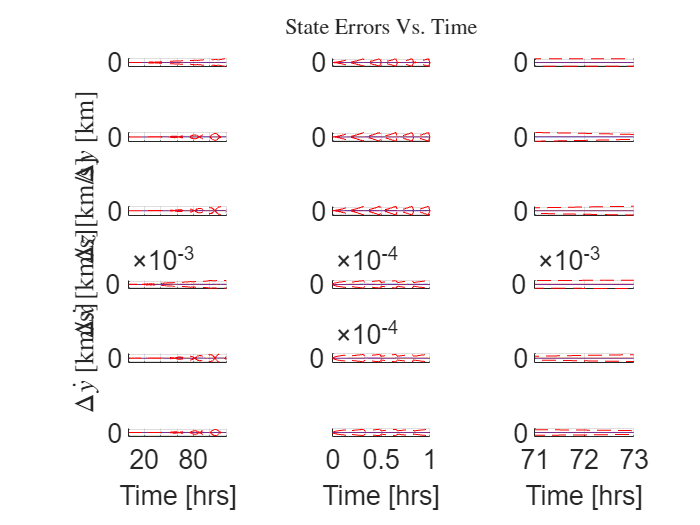

figure;
fig = tiledlayout(n,3);
ylabels =   ["$ \Delta x$ [km]", "$ \Delta y$ [km]","$ \Delta z$ [km/s]", ...
    "$ \Delta\dot x$ [km/s]", "$ \Delta\dot y$ [km/s]","$ \Delta\dot z$ [km/s]"];
for i = 1:n
    sig = mean(squeeze(P_plus_all(i,i,:,:)).^0.5,2);

    nexttile(fig)
    hold on
    for sim = 1:num_sims
        plot(t/60/60,e_X_all(i,:,sim))
    end
    plot(t/60/60,2*sig,'r--')
    plot(t/60/60,-2*sig,'r--')
    hold off
    xlim([1,t_f/60/60])
    ylabel(ylabels(i),Interpreter='latex')
    grid on
    if i == n 
        xlabel("Time [hrs]")
    else
        set(gca,'Xticklabel',[]) %to just get rid of the numbers but leave the ticks.
    end

    nexttile(fig)
    hold on
    for sim = 1:num_sims
        plot(t/60/60,e_X_all(i,:,sim))
    end
    plot(t/60/60,2*sig,'r--')
    plot(t/60/60,-2*sig,'r--')
    hold off
    xlim([0,1])
    grid on
    if i == n 
        xlabel("Time [hrs]")
    else
        set(gca,'Xticklabel',[]) %to just get rid of the numbers but leave the ticks.
    end

    nexttile(fig)
    hold on
    for sim = 1:num_sims
        plot(t/60/60,e_X_all(i,:,sim))
    end
    plot(t/60/60,2*sig,'r--')
    plot(t/60/60,-2*sig,'r--')
    hold off
    xlim([71,73])
    grid on
    if i == n 
        xlabel("Time [hrs]")
    else
        set(gca,'Xticklabel',[]) %to just get rid of the numbers but leave the ticks.
    end
end
title(fig,"State Errors Vs. Time", Interpreter='latex')
set(findall(gcf,'-property','FontSize'),'FontSize',16)

### NEES Plot

The average at every time should be n=6. The variance at every time should be 2n = 12. 

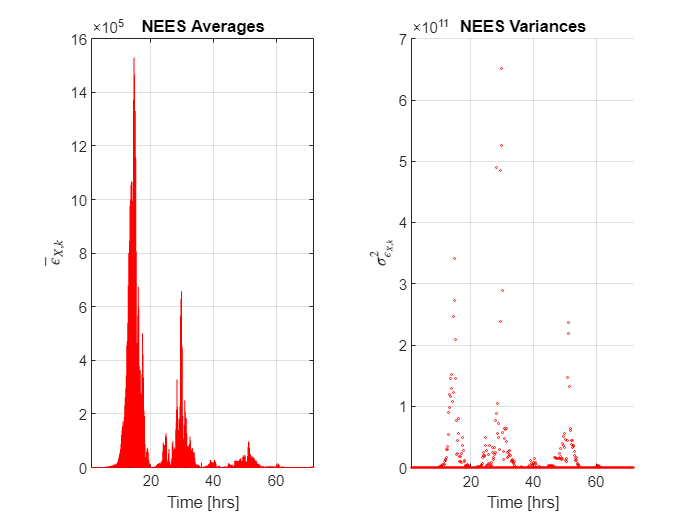

figure;
fig = tiledlayout(1,2);
nexttile(fig)
% scatter(t/60/60,(mean(eps_X_all,2)),1,'red')
plot(t/60/60,(mean(eps_X_all,2)),'red')
grid on 
xlabel("Time [hrs]")
xlim([1,72])
ylabel("$\bar{\epsilon}_{X,k}$",Interpreter='latex')
title("NEES Averages")

nexttile(fig)
scatter(t/60/60,(var(eps_X_all')),1,'red')
grid on 
xlabel("Time [hrs]")
xlim([1,72])
ylabel("$\sigma^2_{\epsilon_{X,k}}$",Interpreter='latex')
title("NEES Variances")

### NIS Plot

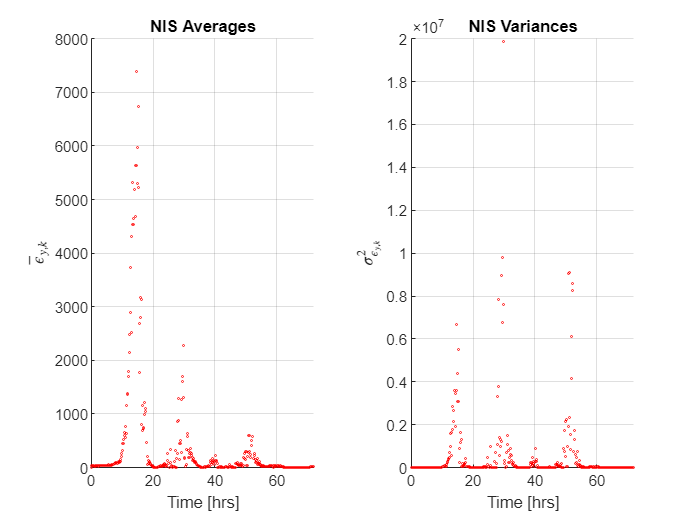

figure;
fig = tiledlayout(1,2);
nexttile(fig)
scatter(t_obs/60/60,(mean(eps_y_all')),1,'red')
grid on 
xlabel("Time [hrs]")
xlim([0,72])
ylabel("$\bar{\epsilon}_{y,k}$",Interpreter='latex')
title("NIS Averages")

nexttile(fig)
scatter(t_obs/60/60,(var(eps_y_all')),1,'red')
grid on 
xlabel("Time [hrs]")
xlim([0,72])
ylabel("$\sigma^2_{\epsilon_{y,k}}$",Interpreter='latex')
title("NIS Variances")